# Mass Balance on Tank

Code author: Dr. Robert Hesketh, [hesketh@rowan.edu](mailto:hesketh@rowan.edu)

Source: Example 10.2-1 from Elementary Principles of Chemical Processes, 4th Ed, R.M. Felder, R.W. Rousseau, L. G. Bullard, John Wiley & Sons, 2018

# Chemical Engineering Summer School Workshop Objectives

- Make a copy of this template and then modify this template by replacing $$$\dot{m}_{out}=\rho\, (0.0025\,m^3/s) t$$$ with $$\dot{m}_{OUT}=\frac{4.77{kg}^{0.5}}{s}m^{0.5}$ where $m$ is the mass in the tank.$

- Discuss the difficulties that you had in modifying this template.

# Objectives

- Derive a mass balance on a stirred tank with an inlet and outlet

- Obtain an analytical expression for the mass of liquid in the tank with a constant flowrate in and and time varying flowrate out of the form mOUT=k*t

- Using MATLAB or python to integrate the mass balance and construct a plot and table of the mass of water in the tank as a function of time.

- Modify this template by replacing $$$\dot{m}_{out}=\rho\, (0.0025\,m^3/s) t$$$ with $$$\dot{m}_{out}=km^{0.5}$$$

- Create and solve a problem in which you have 2 tanks in series. Make a plot of mass in each tank.

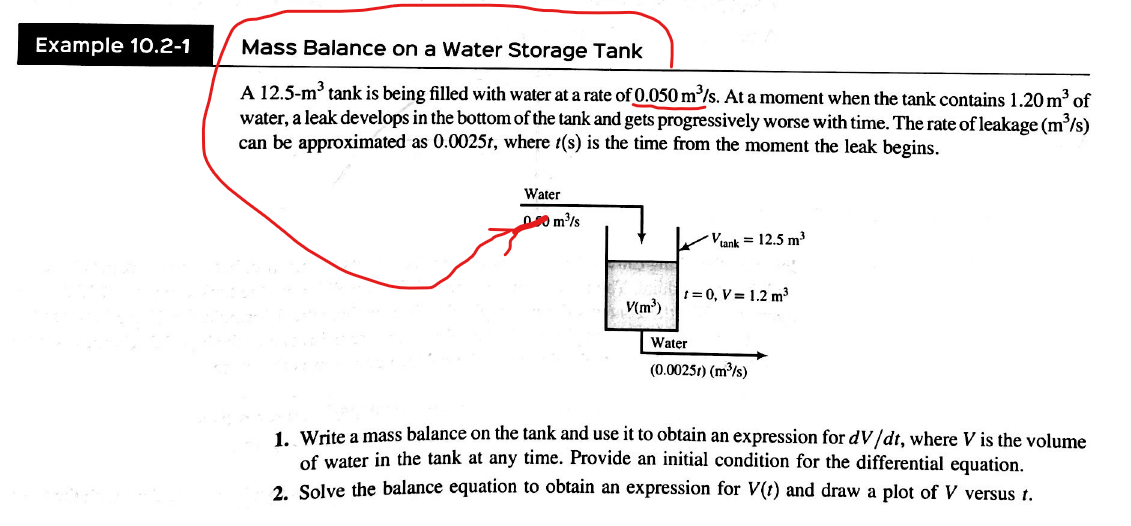

Source: Elementary Principles of Chemical Processes of Chemical Processes Student Workbook, 4th Ed, R.M. Felder, R.W. Rousseau, G.S. Huvard, John Wiley & Sons, 2018

The equations below are written in LaTeX.  To alter these equation double click on the equations and you will get an Edit Equation screen shown below.  You enter the LaTeX commands in the top box and as you type the equations appear in the lower box!  For additional information on LaTeX in MATLAB click [here](https://www.mathworks.com/help/matlab/matlab_prog/insert-equations.html).

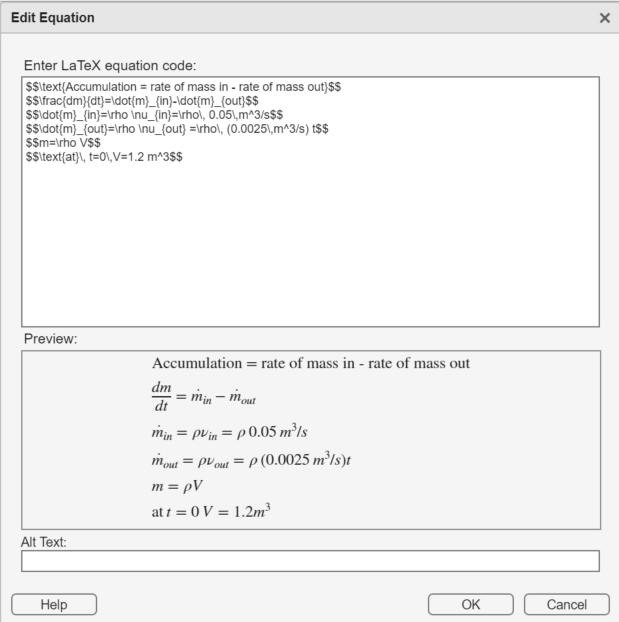

The control volume of this system is the water in the tank with a mass m or volume V

The equations for this problem are the following:


$$$$\text{Accumulation = rate of mass in - rate of mass out}$$ 
$$\frac{dm}{dt}=\dot{m}_{in}-\dot{m}_{out}$$ 
$$\dot{m}_{in}=\rho \nu_{in}=\rho\, 0.05\,m^3/s$$
$$\dot{m}_{out}=\rho \nu_{out} =\rho\, (0.0025\,m^3/s) t$$
$$m=\rho V$$
$$\text{at}\, t=0\,V=1.2 m^3$$

$$


Assuming constant density the mass balance results in a volume balance


$$$$\frac{dV}{dt}=0.05\,m^3/s-(0.0025\,m^3/s^2) t$$$$


Notice that the units of $$0.0025t[=]m^3/s$$ so the units of the constant are $$0.0025 m^3/s^2$$

The analytical solution to this derivative is obtained as follows


$$$$\int_{1.2m^3}^V(\frac{dV}{dt})dt=\int_0^{80s} \left(0.05\frac{m^3}{s}-(0.0025\frac{m^3}{s^2}) t\right) dt$$
$$V\bigg|_{1.2m^3}^V= \left(0.05\frac{m^3}{s}t-(0.0025\frac{m^3}{s^2}) \frac{t^2}{2}\bigg|_0^{t}\right)$$
$$V=1.2m^3+0.05\frac{m^3}{s}t-(0.00125\frac{m^3}{s^2})t^2$$$$


We will solve this problem with both the numerical and the analytical solutions.  Below is the flowchart for the numerical solution:

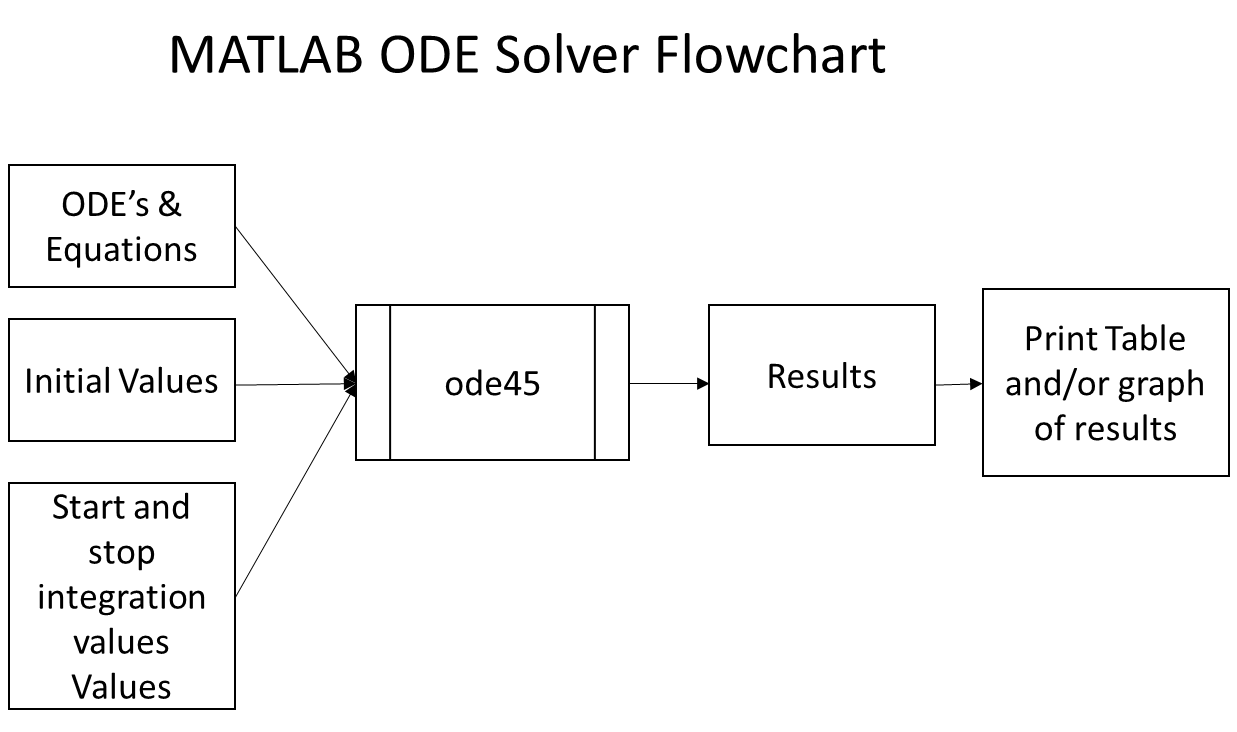

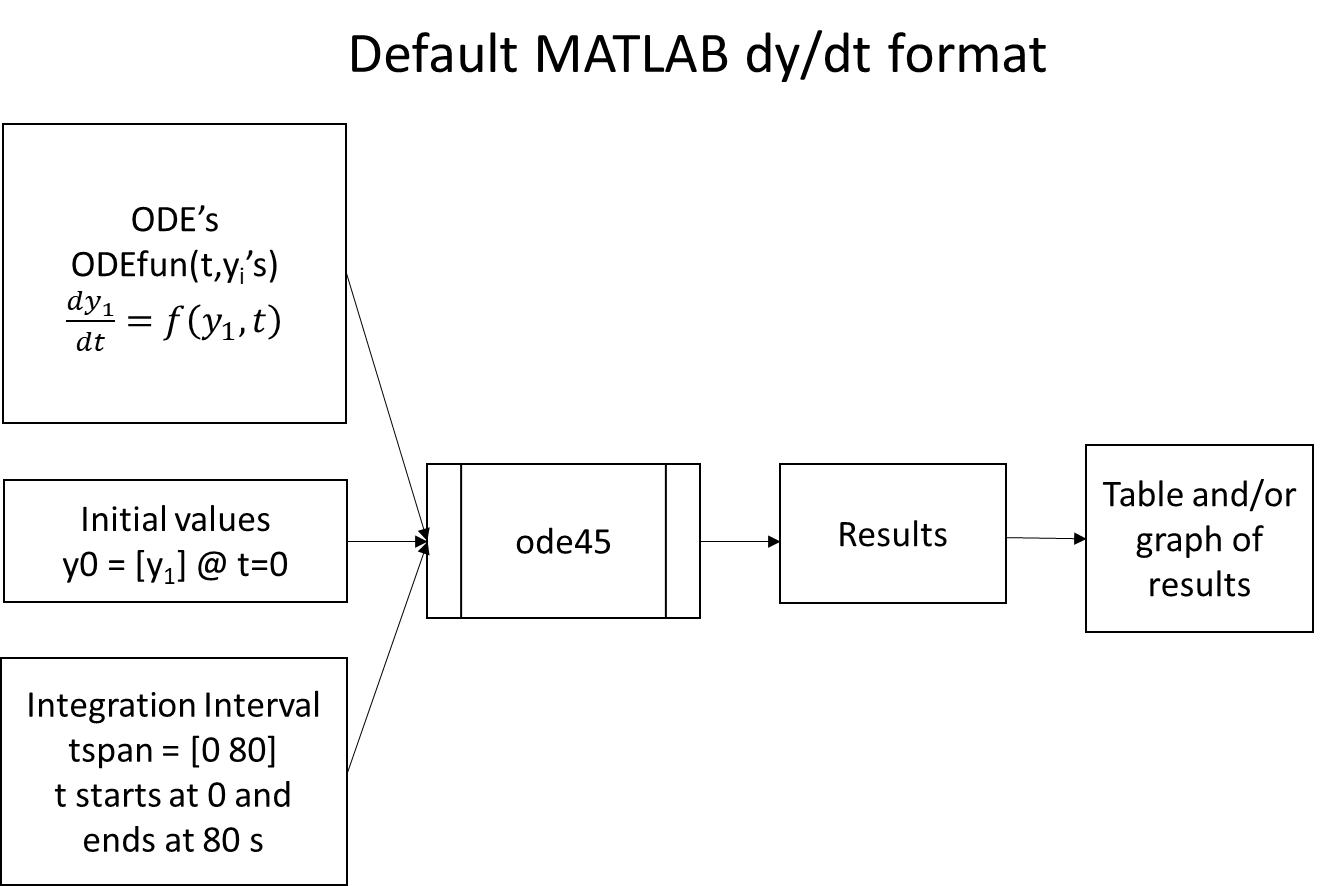

# Procedure

- Derive differential equations for the python model of your system (*e.g.* dy/dt=a-b*t)

- Create a function in MATLAB live editor that contains the differential equations (*e.g.* dy/dt=a-b*t) This must be placed at the end of the live script file (*.mlx)*

- *The function name is defined using ****function*** outputvariable=FUNCTIONname (t,Yfuncvec):

- we will use ODEfun for the FUNCTIONname. After the function name and within parenthesis you then list the variables passed into the function: t and Yfuncvec. 

-  first line of code: unpackthe y vector (which in this example is just V)  V = Yfuncvec(1) This allows you to use the variable name V in the equations in the function

- define the derivative using typed variables. (*e.g.* dVdt=0.05-0.0025*t )

- create an array of the values of the derivative defined above. ( *e.g.* dYfuncvecdt = [dVdt]) Again for this case it is only one derivative

- End the function with the line command ***end***

- Notice that all lines in a function have to be indented. (See below lins 6-10 are indented)

- Give the initial conditions (*e.g.* at t=0 what is y) as tspan=[0,80] for 0 to 80 s

- Give the initial values of the variables. for two tanks that have 100 kg each y0=[100,100]

## Clear the output in the "command window" using clear, clc and set the default format to short g and compact;

`clear`                        c`lear variables and functions from memory and removes all variables from the workspace.`

`clc`                            clears all the text from the Command Window

`format short g`      displays numeric values with wither a 5-digit fixed or floating point

`format compact`      suppresses excess line feeds to show more output in a single screen.

More information about these commands can be found by right clicking command in the  code section. 

clear, clc, format short g, format compact

Below is the text required in the function the contains the differential equation $$$\frac{dV}{dt}=0.05\,m^3/s-(0.0025\,m^3/s^2) t$$$  This is the main part that the user needs to modify to solve a system of ODE's.  This actual function is located at the end of the file.

## What is in the function containing the ODE's?

Again this function is located at the end of the file or click on Functions

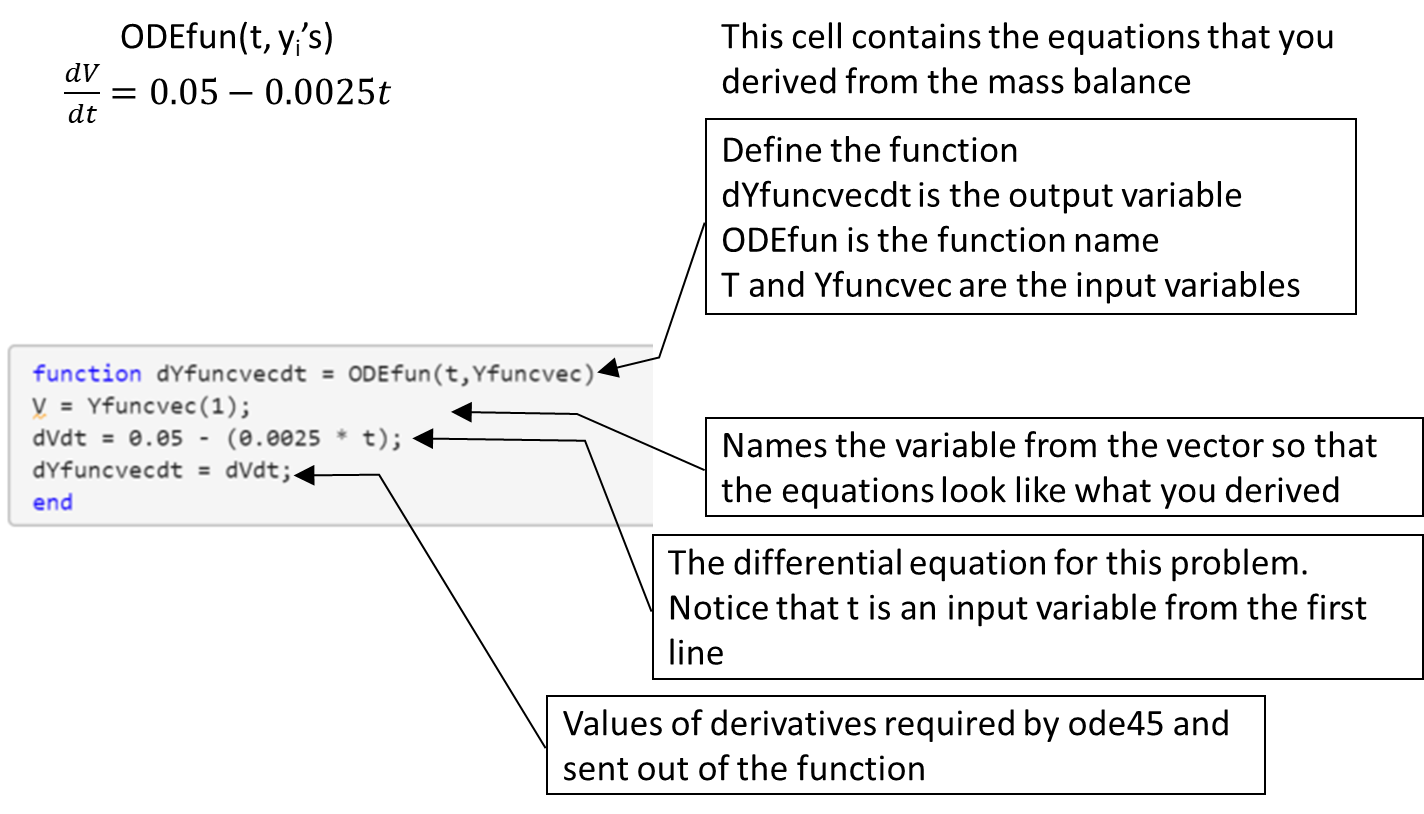

## Now let's test the function.  

The graphic below gives more details on how to test the function and the formatted output.

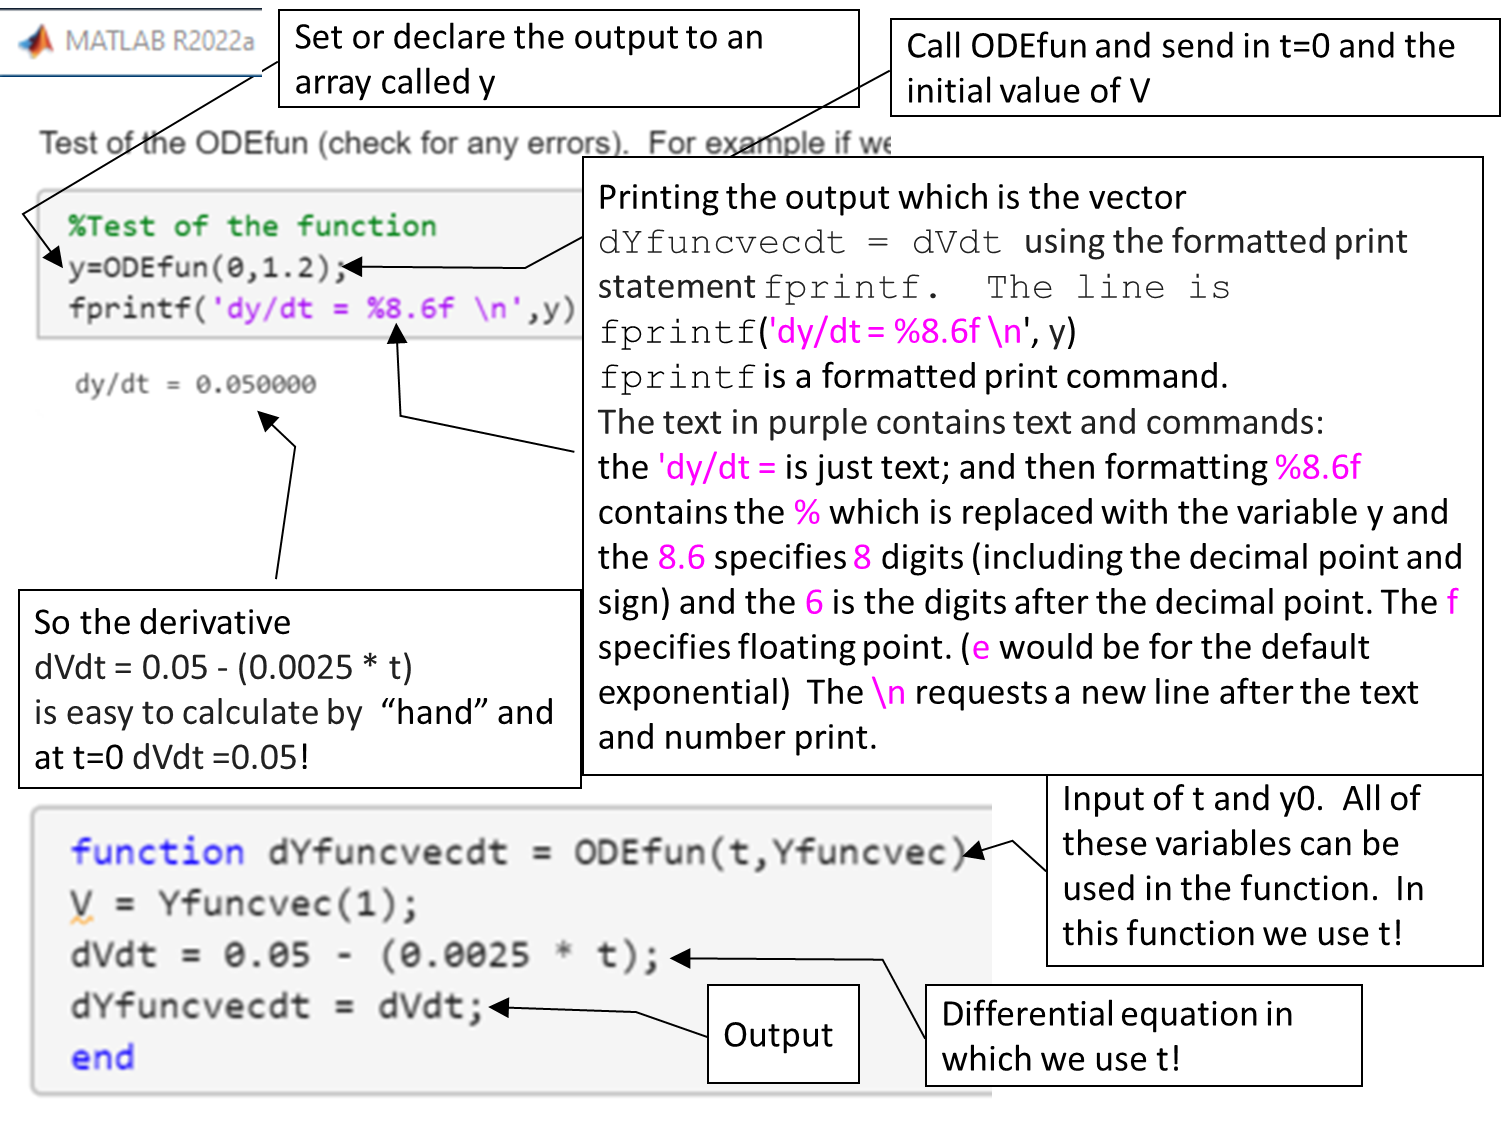

Test of the ODEfun (check for any errors).  For example if we send in t=0 and V=1.2 then the value of dVdt should equal 0.05.

%Test of the function
y=ODEfun(0,1.2);
fprintf('dy/dt = %8.6f \n',y)

dy/dt = 0.050000 


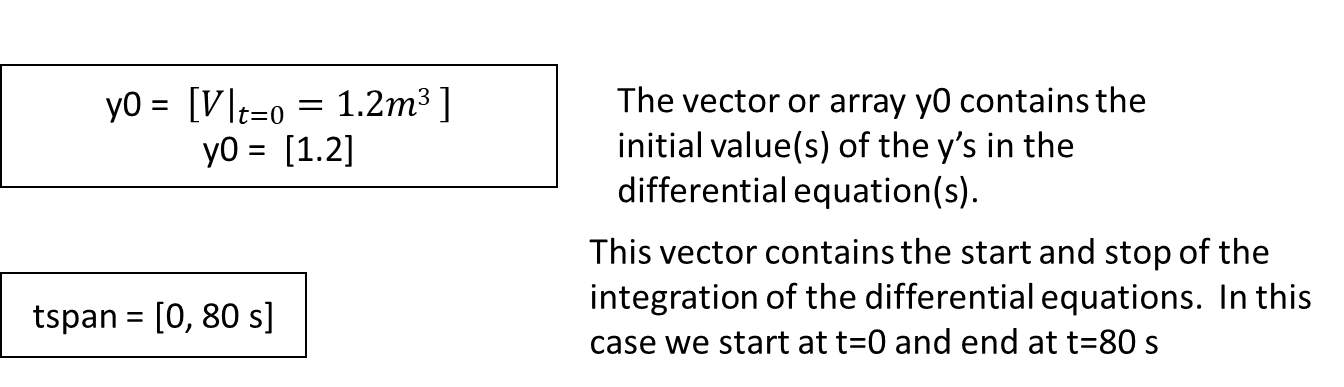

y0 = 1.2; % Initial values for the dependent variables
tspan = [0 80]; % Range for the independent variable

## Solve the ODE!

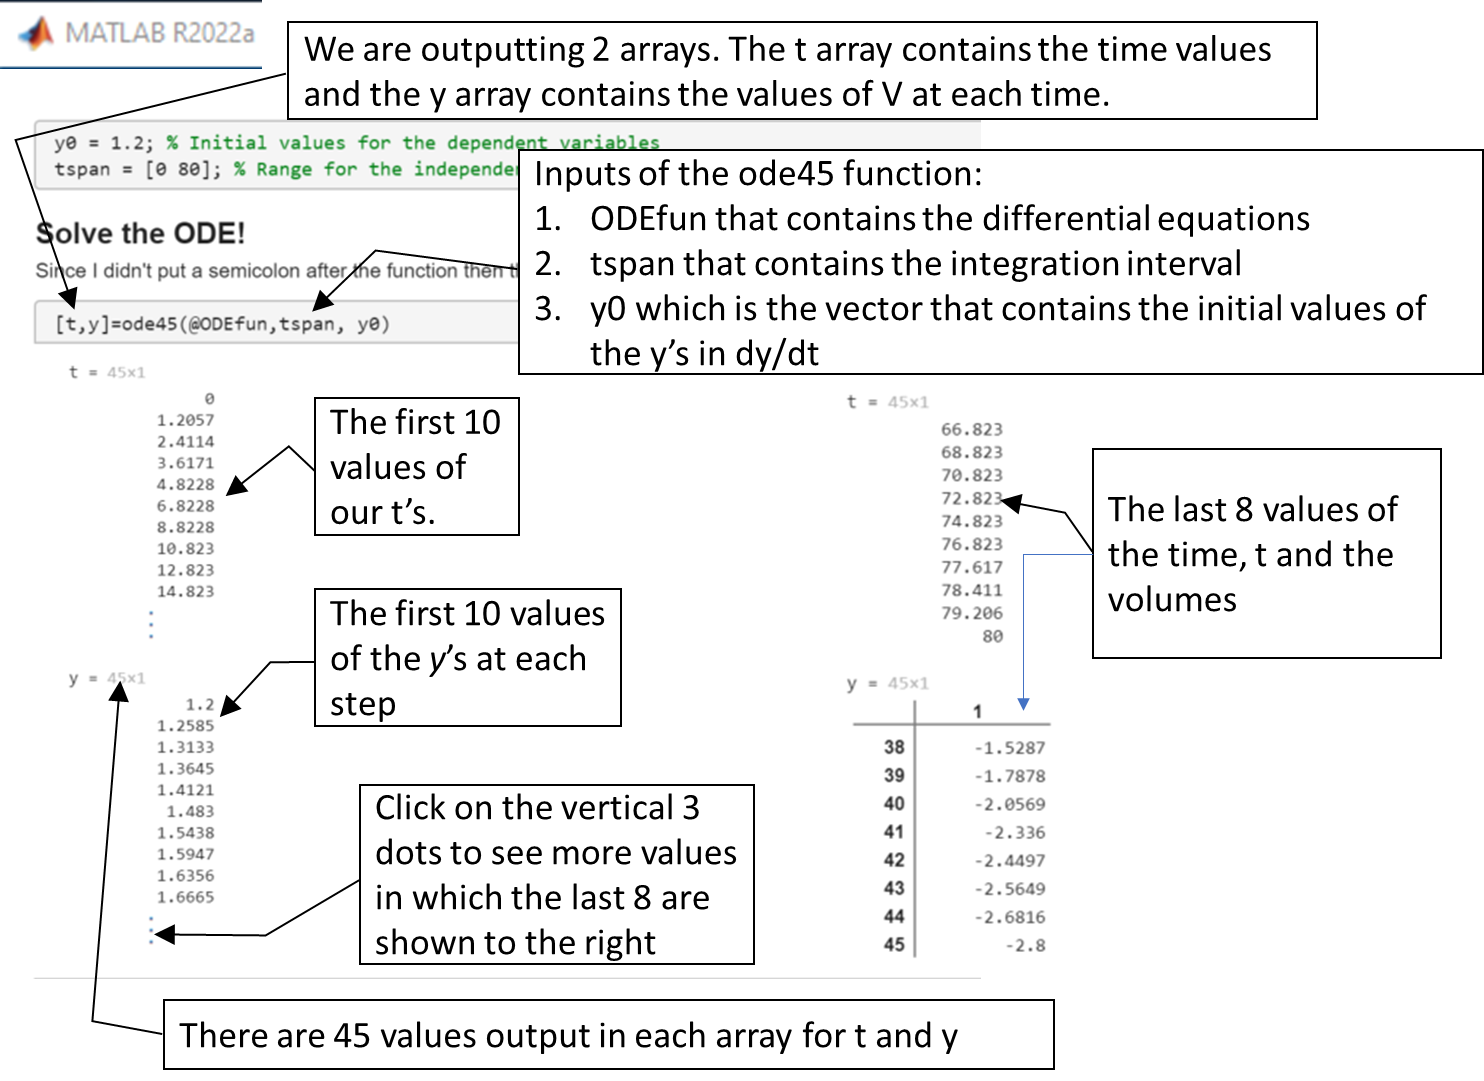

Since I didn't put a semicolon after the function then the values of t and y (in this case $V$) are printed out.

Below is the call of the MATLAB integration function ode45

[t,y]=ode45(@ODEfun,tspan, y0)

t =             0
       1.2057
       2.4114
       3.6171
       4.8228
       6.8228
       8.8228
       10.823
       12.823
       14.823


y =           1.2
       1.2585
       1.3133
       1.3645
       1.4121
        1.483
       1.5438
       1.5947
       1.6356
       1.6665


# Print a table of the ODE output

The following prints 45 rows of 2 columns of numbers with no headers.  This is done by just removing the semicolon.  The problem with this output is that you would lose points since the grader wouldn't know what variables that you plotted!

large=[t,y]

large =             0          1.2
       1.2057       1.2585
       2.4114       1.3133
       3.6171       1.3645
       4.8228       1.4121
       6.8228        1.483
       8.8228       1.5438
       10.823       1.5947
       12.823       1.6356
       14.823       1.6665


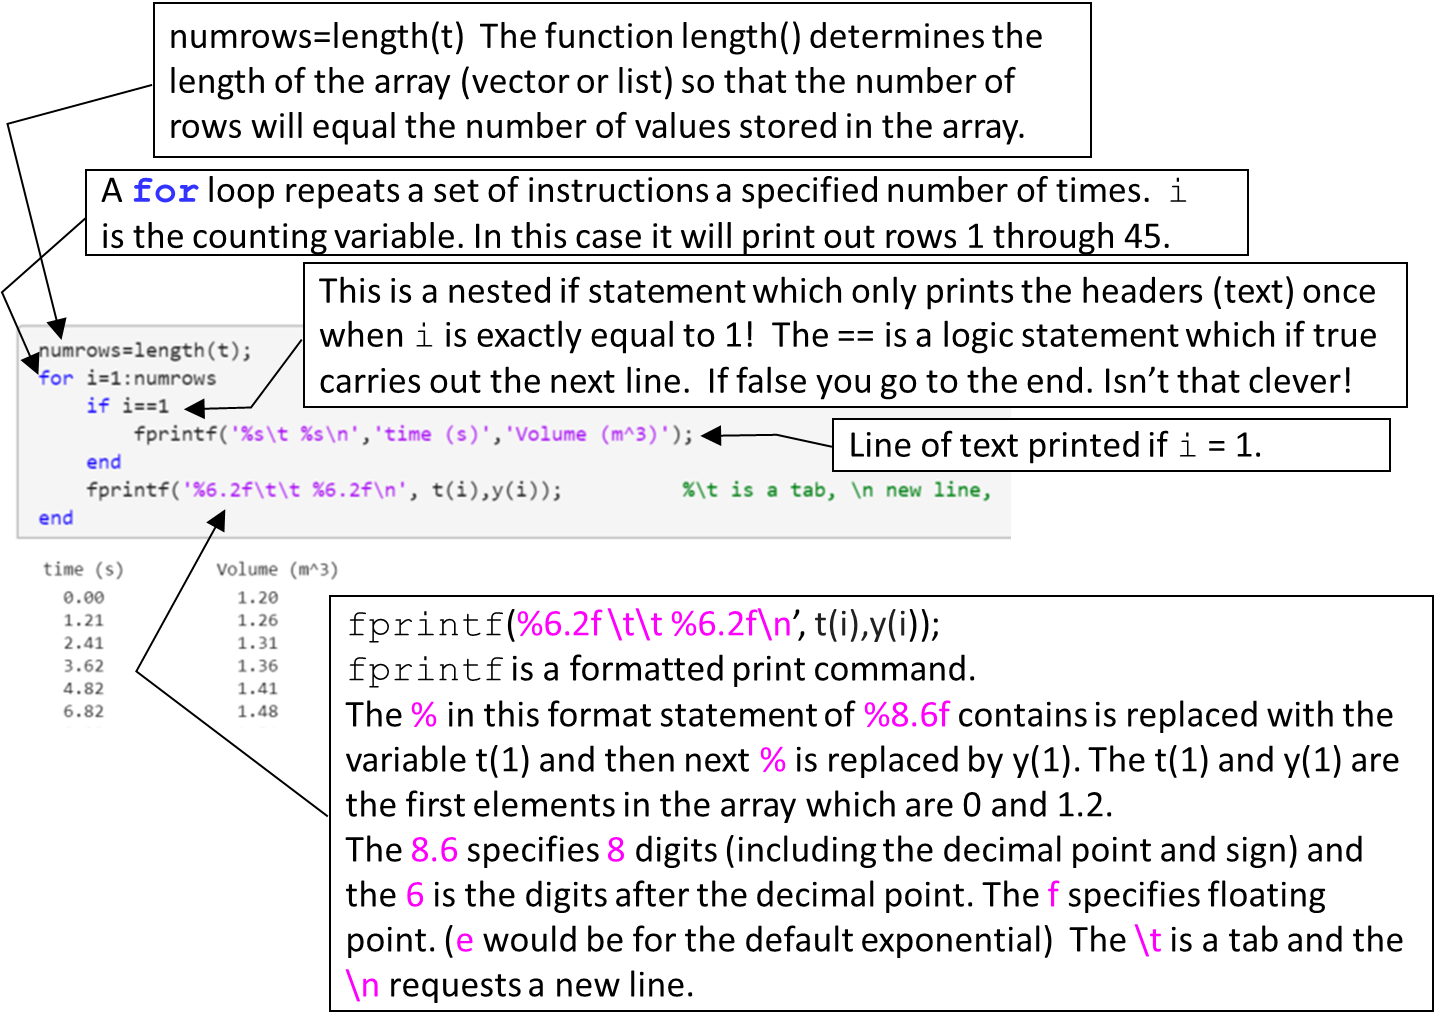

The following prints 45 rows of 2 columns of numbers with **headers** using a for loop

numrows=length(t);
for i=1:numrows
    if i==1
        fprintf('%s\t %s\n','time (s)','Volume (m^3)');
    end
    fprintf('%6.2f\t\t %6.2f\n', t(i),y(i));          %\t is a tab, \n new line, 
end

time (s)	 Volume (m^3)


  0.00		   1.20
  1.21		   1.26
  2.41		   1.31
  3.62		   1.36
  4.82		   1.41
  6.82		   1.48
  8.82		   1.54
 10.82		   1.59
 12.82		   1.64
 14.82		   1.67
 16.82		   1.69
 18.82		   1.70
 20.82		   1.70
 22.82		   1.69
 24.82		   1.67
 26.82		   1.64
 28.82		   1.60
 30.82		   1.55
 32.82		   1.49
 34.82		   1.43
 36.82		   1.35
 38.82		   1.26
 40.82		   1.16
 42.82		   1.05
 44.82		   0.93
 46.82		   0.80
 48.82		   0.66
 50.82		   0.51
 52.82		   0.35
 54.82		   0.18
 56.82		   0.01
 58.82		  -0.18
 60.82		  -0.38
 62.82		  -0.59
 64.82		  -0.81
 66.82		  -1.04
 68.82		  -1.28
 70.82		  -1.53
 72.82		  -1.79
 74.82		  -2.06
 76.82		  -2.34
 77.62		  -2.45
 78.41		  -2.56
 79.21		  -2.68
 80.00		  -2.80


### That table is too long! 

A table is usually only a summary of information so maybe only 11 rows is needed for a table.  I typically take points off if you give me a summary table of every point produced by a function. 

Also we didn't print out the analytical solution! 

The analytical solution to this derivative is obtained as follows


$$$$\int_{1.2m^3}^V(\frac{dV}{dt})dt=\int_0^{80s} \left(0.05\frac{m^3}{s}-(0.0025\frac{m^3}{s^2}) t\right) dt$$$$



$$$$V\bigg|_{1.2m^3}^V= \left(0.05\frac{m^3}{s}t-(0.0025\frac{m^3}{s^2}) \frac{t^2}{2}\bigg|_0^{t}\right)$$$$



$$$$V=1.2m^3+0.05\frac{m^3}{s}t-(0.00125\frac{m^3}{s^2})t^2$$$$


numrows=11;
teval = linspace( tspan(1),tspan(2) , numrows );
[t,y]=ode45(@ODEfun,teval, y0);
Vanal(numrows)=0;
numrows=length(t);
for i=1:numrows
    if i==1
        fprintf('%s\t %s\t %s\n','time ','V (numerical) ', 'V (analytical) ');
        fprintf('%s\t\t %s\t\t %s\n',' (s)','(m^3)', ' (m^3)');
    end
    Vanal(i)=1.2+0.05*t(i)-0.00125*t(i)^2;
    fprintf('%6.2f\t\t %6.2f\t\t %6.2f\n', t(i),y(i), Vanal(i));          %\t is a tab, \n new line, 
end

time 	 V (numerical) 	 V (analytical) 


 (s)		 (m^3)		  (m^3)


  0.00		   1.20		   1.20
  8.00		   1.52		   1.52
 16.00		   1.68		   1.68
 24.00		   1.68		   1.68
 32.00		   1.52		   1.52
 40.00		   1.20		   1.20
 48.00		   0.72		   0.72
 56.00		   0.08		   0.08
 64.00		  -0.72		  -0.72
 72.00		  -1.68		  -1.68
 80.00		  -2.80		  -2.80


## 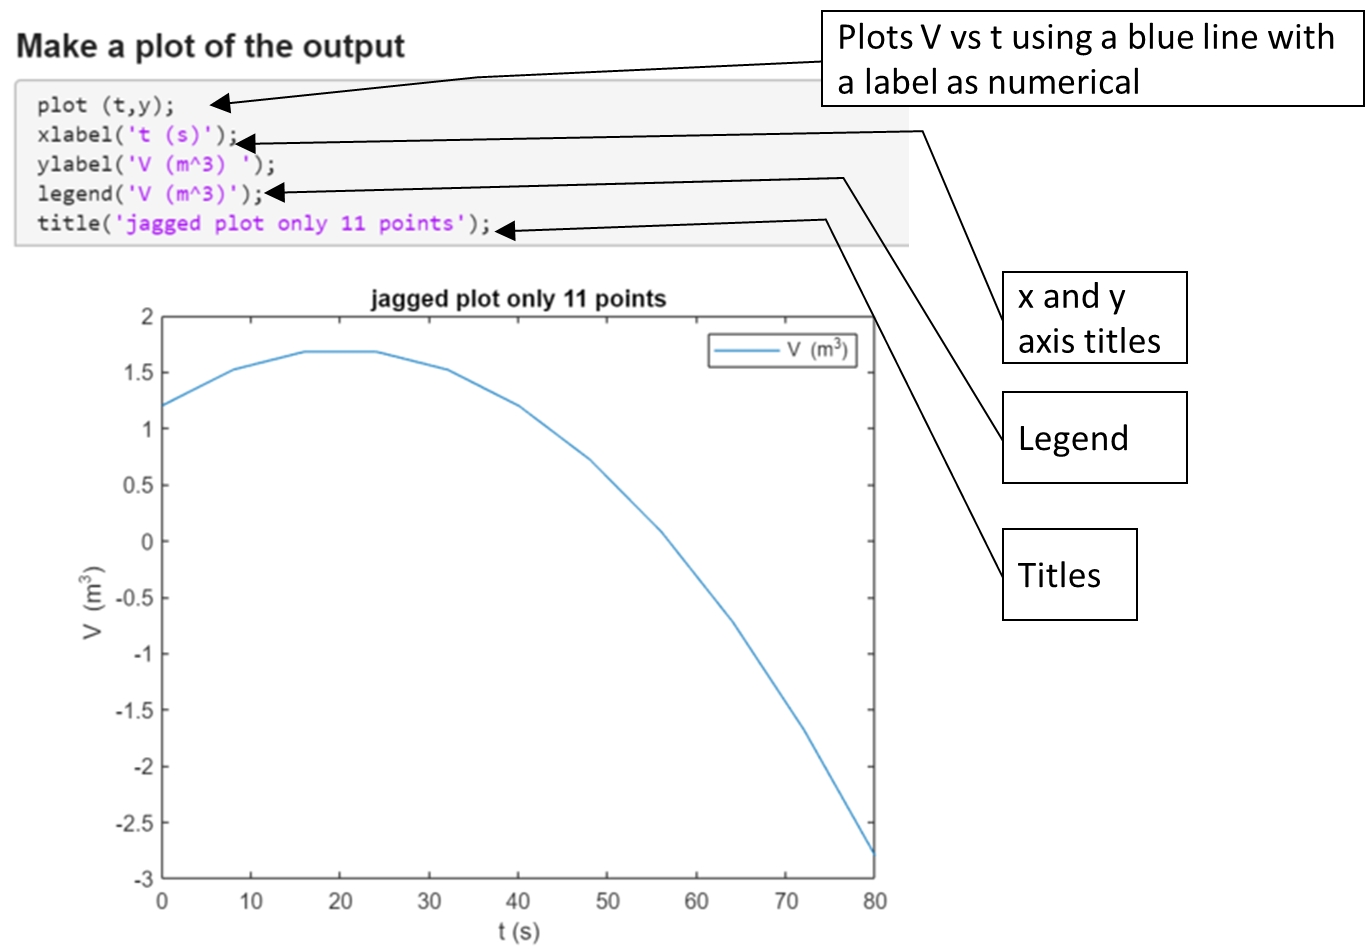

## Make a plot of the output

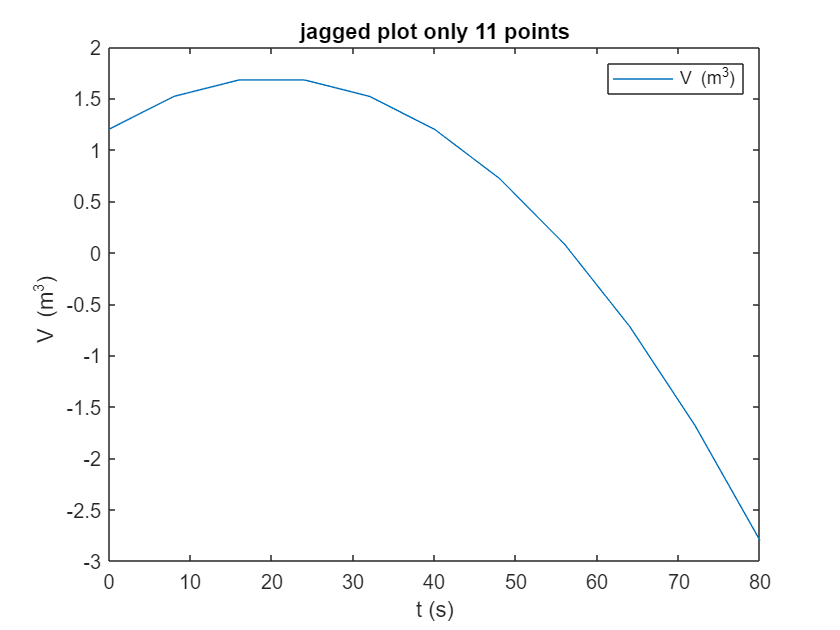

plot (t,y);
xlabel('t (s)');
ylabel('V (m^3) ');
legend('V (m^3)');
title('jagged plot only 11 points');

### Wow that was easy to make a plot!

Notice that the above graph is jagged.  To make a smooth plot you want to use a larger number of points.  The first time we used ode45 we got 45 rows.  Let's plot that data set.

### Now let's plot the results!

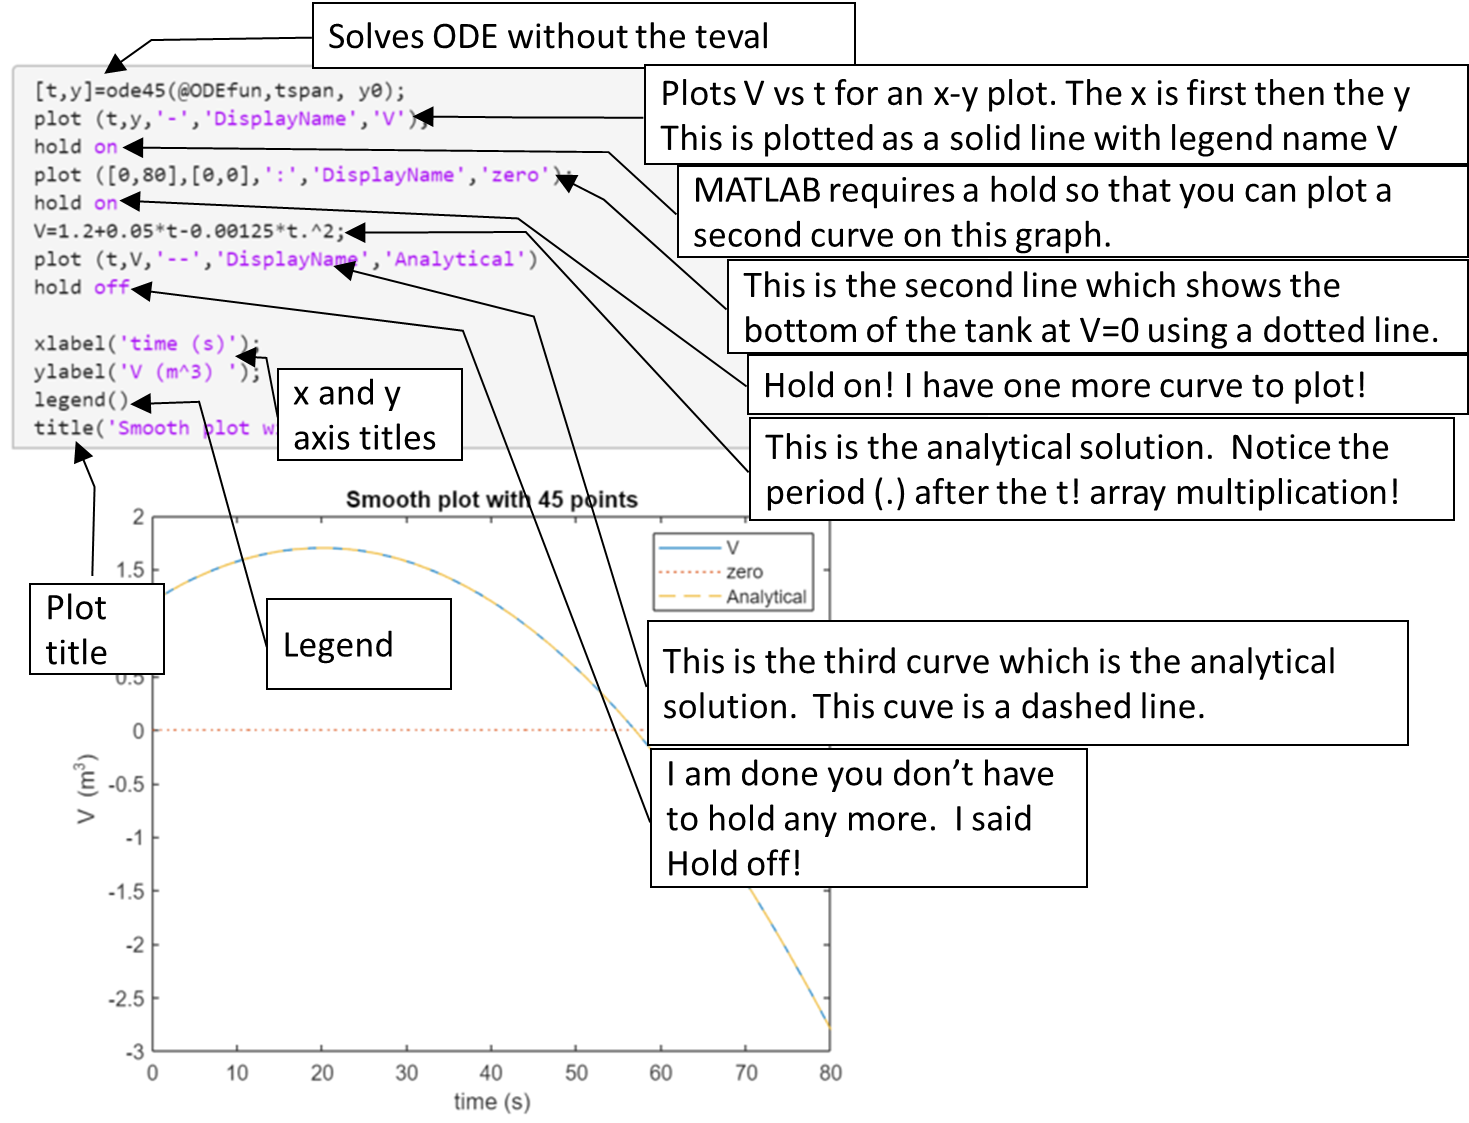

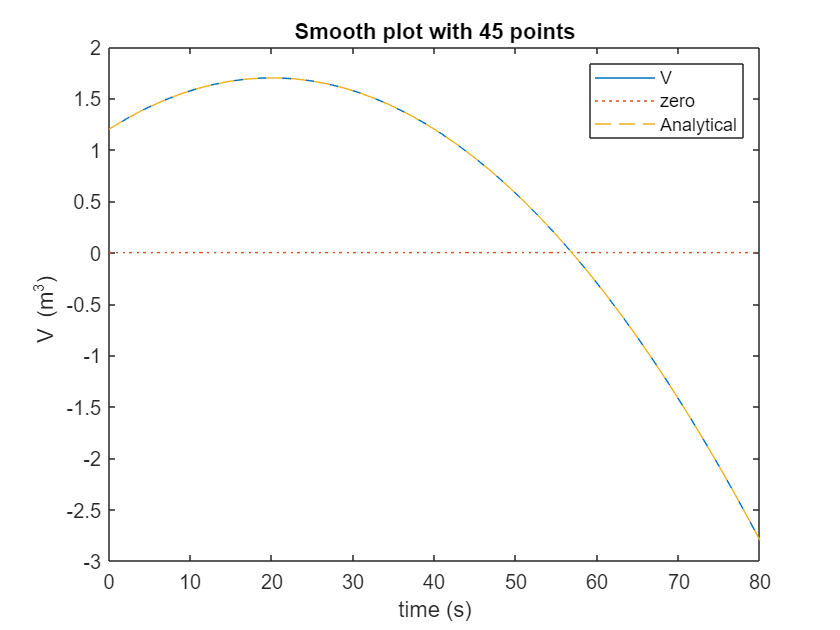

[t,y]=ode45(@ODEfun,tspan, y0);
plot (t,y,'-','DisplayName','V');
hold on
plot ([0,80],[0,0],':','DisplayName','zero');
hold on
V=1.2+0.05*t-0.00125*t.^2;
plot (t,V,'--','DisplayName','Analytical')
hold off

xlabel('time (s)');
ylabel('V (m^3) ');
legend()
title('Smooth plot with 45 points')

## What? You want to know exactly when the tank volume is empty?

- We could estimate it by looking at the graph.  I think it is V=0 at just under 60 s!

- Look at the 45 points that we have already printed and see if one of thosed matches V=0.   This looks like t=58s

- print out 501 points (t is between 56.8 and 56.96 

- put a counter in the function that will stop counting when V<0 (that needs an if statement)

- Solve for the analytical solution to find t! Below this is `draintime=56.8782s (but only with a smaller value thatn the default for the tolerances: AbsTol<=1e-10,RelTol<=1e-6`

This gives a lot of points! which is option 3.

numrows=501;
teval = linspace( tspan(1),tspan(2) , numrows );
[t,y]=ode45(@ODEfun,teval, y0);

for i=1:numrows
    if i==1
        fprintf('%s\t %s\n','time (s)','Volume (m^3)');
    end
    fprintf('%6.4f\t\t %6.4f\n', t(i),y(i));          %\t is a tab, \n new line, 
end

time (s)	 Volume (m^3)


0.0000		 1.2000
0.1600		 1.2080
0.3200		 1.2159
0.4800		 1.2237
0.6400		 1.2315
0.8000		 1.2392
0.9600		 1.2468
1.1200		 1.2544
1.2800		 1.2620
1.4400		 1.2694
1.6000		 1.2768
1.7600		 1.2841
1.9200		 1.2914
2.0800		 1.2986
2.2400		 1.3057
2.4000		 1.3128
2.5600		 1.3198
2.7200		 1.3268
2.8800		 1.3336
3.0400		 1.3404
3.2000		 1.3472
3.3600		 1.3539
3.5200		 1.3605
3.6800		 1.3671
3.8400		 1.3736
4.0000		 1.3800
4.1600		 1.3864
4.3200		 1.3927
4.4800		 1.3989
4.6400		 1.4051
4.8000		 1.4112
4.9600		 1.4172
5.1200		 1.4232
5.2800		 1.4292
5.4400		 1.4350
5.6000		 1.4408
5.7600		 1.4465
5.9200		 1.4522
6.0800		 1.4578
6.2400		 1.4633
6.4000		 1.4688
6.5600		 1.4742
6.7200		 1.4796
6.8800		 1.4848
7.0400		 1.4900
7.2000		 1.4952
7.3600		 1.5003
7.5200		 1.5053
7.6800		 1.5103
7.8400		 1.5152
8.0000		 1.5200
8.1600		 1.5248
8.3200		 1.5295
8.4800		 1.5341
8.6400		 1.5387
8.8000		 1.5432
8.9600		 1.5476
9.1200		 1.5520
9.2800		 1.5564
9.4400		 1.5606
9.6000		 1.5648
9.7600		 1.5689
9.9200		

This is the example with a counter.  I have created a new function ODEfunCount which is given below and the actual function is given at Functions

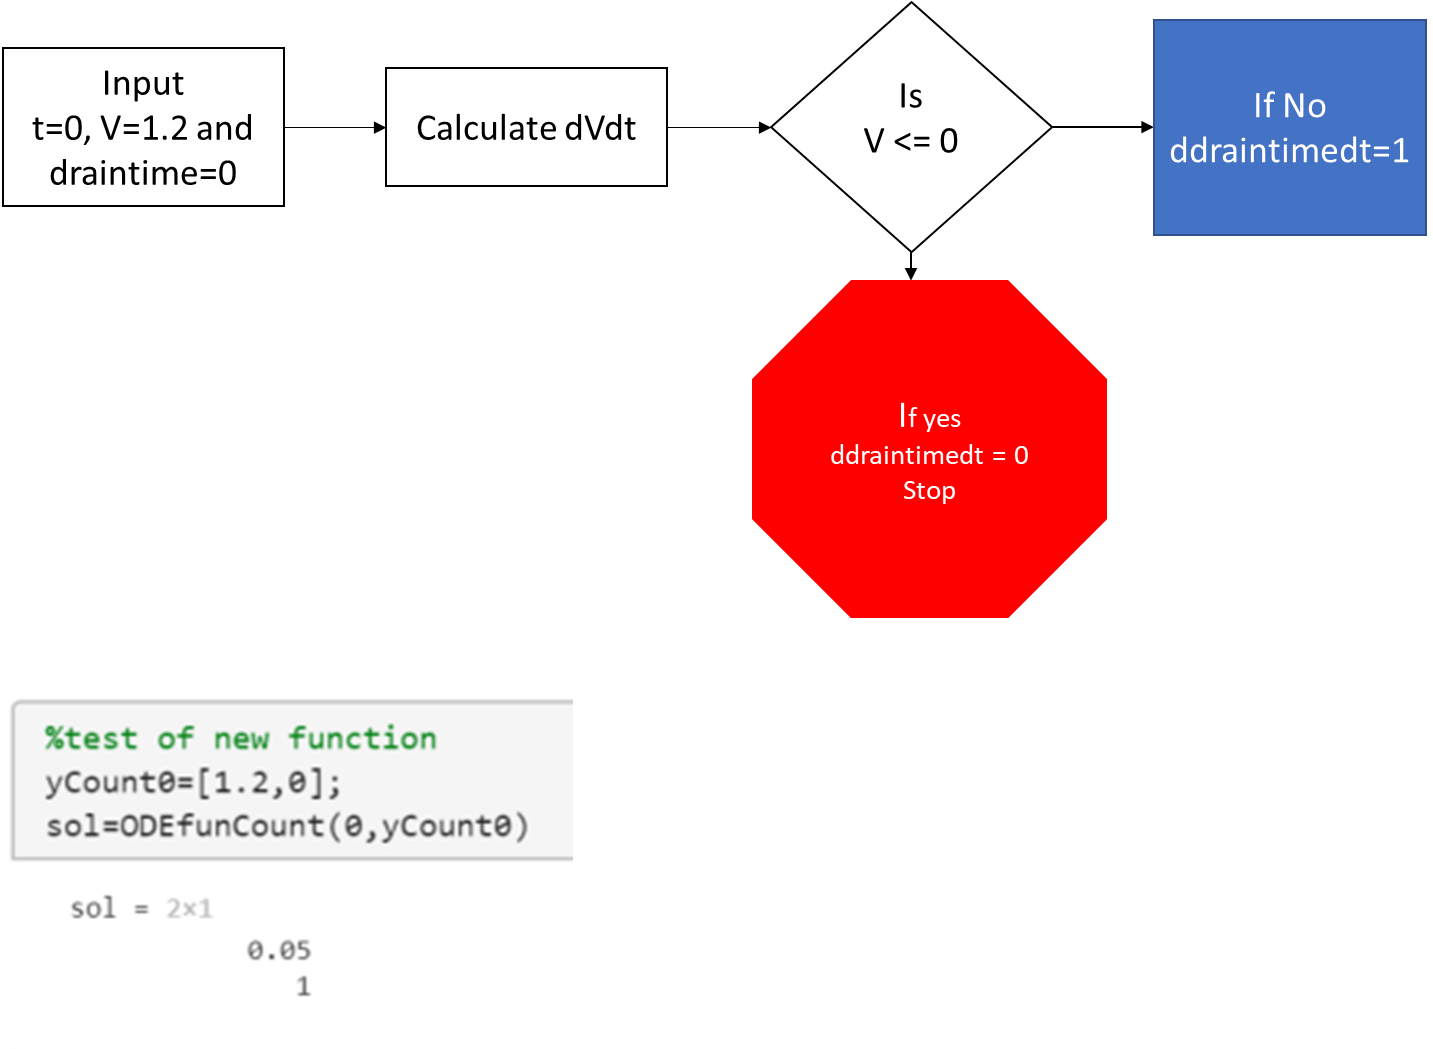

When these derivatives are sent to the ode45 solver the following integrals are evaluated.


$$$$\int_{1.2m^3}^VdV=\int_0^{80s} \left(0.05\frac{m^3}{s}-(0.0025\frac{m^3}{s^2}) t\right) dt$$
$$\text{draintime} =\int_0^{80s}\frac{d\,(\text{draintime})}{dt} dt$$$$


At the start of the draining the derivative is equal to 1 since V>0 and the integral adds up each second.  When V<=0 then the derivative is zero and no more time is added.  The result is the output from the ODE45 is the time to drain the tank.  

%test of new function
yCount0=[1.2,0];
sol=ODEfunCount(0,yCount0)

sol =          0.05
            1


Now we solve using the new counter function and the result is the determination of the drain time which will be the last value of the draintime array.

clc;
yCount0=[1.2; 0];
tspan = [0 80];
numrows=101;
teval = linspace( tspan(1),tspan(2) , numrows );
[t,y]=ode45(@ODEfunCount,teval,yCount0);
fprintf('draintime=%6.4f s\n', y(end,2));%The end specifies the last row and the 2 is the draintime variable.

draintime=56.2478 s


We will see that this time is a little short of the analytical solution, but let's look at the table of numbers first.

Printing out the table with a large number of points so we can find when V=0

numrows=length(t);
for i=1:numrows
    if i==1
        fprintf('%s\t %s\t %s\n','time (s)','Volume (m^3)', 'draintime (s)');
    end
    fprintf('%6.4f\t\t %8.4f\t\t %6.4f\n', t(i),y(i,1),y(i,2));          %\t is a tab, \n new line, 
end

time (s)	 Volume (m^3)	 draintime (s)


0.0000		   1.2000		 0.0000
0.8000		   1.2392		 0.8000
1.6000		   1.2768		 1.6000
2.4000		   1.3128		 2.4000
3.2000		   1.3472		 3.2000
4.0000		   1.3800		 4.0000
4.8000		   1.4112		 4.8000
5.6000		   1.4408		 5.6000
6.4000		   1.4688		 6.4000
7.2000		   1.4952		 7.2000
8.0000		   1.5200		 8.0000
8.8000		   1.5432		 8.8000
9.6000		   1.5648		 9.6000
10.4000		   1.5848		 10.4000
11.2000		   1.6032		 11.2000
12.0000		   1.6200		 12.0000
12.8000		   1.6352		 12.8000
13.6000		   1.6488		 13.6000
14.4000		   1.6608		 14.4000
15.2000		   1.6712		 15.2000
16.0000		   1.6800		 16.0000
16.8000		   1.6872		 16.8000
17.6000		   1.6928		 17.6000
18.4000		   1.6968		 18.4000
19.2000		   1.6992		 19.2000
20.0000		   1.7000		 20.0000
20.8000		   1.6992		 20.8000
21.6000		   1.6968		 21.6000
22.4000		   1.6928		 22.4000
23.2000		   1.6872		 23.2000
24.0000		   1.6800		 24.0000
24.8000		   1.6712		 24.8000
25.6000		   1.6608		 25.6000
26.4000		   1.6488		 26.4000
27.2000		   1.6352		 27.2000
28.0000		  

We can solve the quadratic equation and find the analytical solution


$$$$V=1.2m^3+0.05\frac{m^3}{s}t-(0.00125\frac{m^3}{s^2})t^2=0$$$$


a=-0.00125;
b=0.05;
c=1.2;
draintimeAnal = (-b - sqrt(b^2 - 4*a*c)) / (2*a);
fv=c+b*draintimeAnal+a*draintimeAnal^2;
fprintf('Analytical draintime=%6.4f s\t Percent difference=%6.4f %%\n', draintimeAnal,(y(end,2)-draintimeAnal)/draintimeAnal*100)

Analytical draintime=56.8782 s	 Percent difference=-1.1082 %


Since this solution of doesn't match the result from ODEfunCount (1.1% difference) we will specify a smaller value for the relative and absolute tolerances in the ode45 solver using 

clc;
yCount0=[1.2; 0];
tspan = [0 80];
numrows=101;
teval = linspace( tspan(1),tspan(2) , numrows );
options = odeset('AbsTol',1e-10,'RelTol',1e-6);
[t,y]=ode45(@ODEfunCount,teval,yCount0,options);
numrows=length(t);
for i=1:numrows
    if i==1
        fprintf('%s\t %s\t %s\n','time (s)','Volume (m^3)', 'draintime (s)');
    end
    fprintf('%6.4f\t\t %8.4f\t\t %6.4f\n', t(i),y(i,1),y(i,2));          %\t is a tab, \n new line, 
end

time (s)	 Volume (m^3)	 draintime (s)


0.0000		   1.2000		 0.0000
0.8000		   1.2392		 0.8000
1.6000		   1.2768		 1.6000
2.4000		   1.3128		 2.4000
3.2000		   1.3472		 3.2000
4.0000		   1.3800		 4.0000
4.8000		   1.4112		 4.8000
5.6000		   1.4408		 5.6000
6.4000		   1.4688		 6.4000
7.2000		   1.4952		 7.2000
8.0000		   1.5200		 8.0000
8.8000		   1.5432		 8.8000
9.6000		   1.5648		 9.6000
10.4000		   1.5848		 10.4000
11.2000		   1.6032		 11.2000
12.0000		   1.6200		 12.0000
12.8000		   1.6352		 12.8000
13.6000		   1.6488		 13.6000
14.4000		   1.6608		 14.4000
15.2000		   1.6712		 15.2000
16.0000		   1.6800		 16.0000
16.8000		   1.6872		 16.8000
17.6000		   1.6928		 17.6000
18.4000		   1.6968		 18.4000
19.2000		   1.6992		 19.2000
20.0000		   1.7000		 20.0000
20.8000		   1.6992		 20.8000
21.6000		   1.6968		 21.6000
22.4000		   1.6928		 22.4000
23.2000		   1.6872		 23.2000
24.0000		   1.6800		 24.0000
24.8000		   1.6712		 24.8000
25.6000		   1.6608		 25.6000
26.4000		   1.6488		 26.4000
27.2000		   1.6352		 27.2000
28.0000		  

fprintf('draintime=%6.4f s\n', y(end,2))

draintime=56.8756 s


fprintf('Analytical draintime=%6.4f s\t Percent difference=%6.4f %%\n', draintimeAnal,(y(end,2)-draintimeAnal)/draintimeAnal*100)

Analytical draintime=56.8782 s	 Percent difference=-0.0045 %


Now the difference is less than 0.01 %

## Further work:  Modify this template by replacing $$$\dot{m}_{out}=\rho\, (0.0025\,m^3/s) t$$$ with $$\dot{m}_{OUT}=\frac{4.77{kg}^{0.5}}{s}m^{0.5}$ where $m$ is the mass in the tank.$

## Additional Work:

Create a simulation of 2 tanks in series in which the fluid leaving the first and second tanks is proportional to the $V^{0.5}$ and the feed to the first tank is a constant flowrate.  Make a plot of mass in each tank.

## Functions

function dYfuncvecdt = ODEfun(t,Yfuncvec)
V = Yfuncvec(1);
dVdt = 0.05 - (0.0025 * t);
dYfuncvecdt = dVdt;
end

function dYfuncvecdt = ODEfunCount(t,Yfuncvec)
V = Yfuncvec(1);
draintime = Yfuncvec(2);
dVdt = 0.05 - (0.0025 * t);
if (V <= 0)
   ddraintimedt = 0;
else
   ddraintimedt = 1;
end
dYfuncvecdt = [dVdt; ddraintimedt];
end